# Slosh 3D, tilt about y axis 

Different parametrization of the pendulum

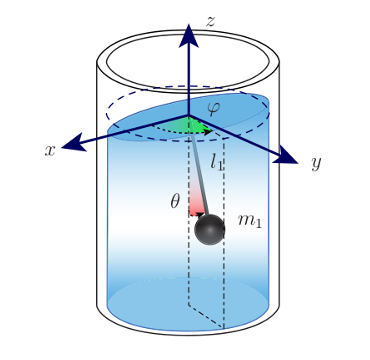

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the y axis of the container.

clc 
clear all

syms theta(t) psi(t) phi(t) beta(t)
syms t 
syms d h l m g M b cs
syms x(t) y(t) z(t)
sympref('AbbreviateOutput',false);

$\theta$ = second rotation about Y describing the sloshing

$\phi$ = first rotation abouy Z describing the plane of sloshing

$\beta$ = pitch rotation about the x axis of the container

h = height of the container

d = distance from CoM to top of the liquid at rest (for full uniform liquid container it is h/2)

l = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container CoM with origin assumed to be at a distance d from the pivot

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to CoM

Derive the homogeneous transformation matrix from the world to the CoM reference frame.

Define rotation matrix (rotation of around the y-axis)

% Rotation matrix about y-axis of angle beta
R_y_beta = [cos(beta),  0, sin(beta); 
             0,           1,           0; 
             -sin(beta),  0,  cos(beta)];
R_y_beta=formula(R_y_beta)

$$R\_y\_beta = \left(\begin{array}{ccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [x; y; z];

Create homogeneous transformation matrix

T_wg = [R_y_beta, p; 0 0 0 1];
T_wg = formula(T_wg);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to CoM:');

Homogeneous Transformation Matrix from world to CoM:


disp(T_wg);

$$\left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right) & x\left(t\right)\\ 0 & 1 & 0 & y\left(t\right)\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### CoM to pivot

Derive the homogeneous transformation matrix from the CoM reference frame to the pivot reference frame.

Define rotation matrices

% First rotation about z
R_z_phi = [cos(phi),  -sin(phi), 0;
           sin(phi),   cos(phi), 0;
           0,          0,        1];

% Second rotation about y
R_y_theta = [cos(-theta),  0,  sin(-theta);
              0,            1,            0;
             -sin(-theta),  0,  cos(-theta)];

% Third rotation about z
R_z_phi_minus = [cos(-phi),  -sin(-phi), 0;
               sin(-phi),   cos(-phi), 0;
               0,          0,        1];

R_combined = R_z_phi * R_y_theta %* R_z_phi_minus

$$R\_combined(t) = \left(\begin{array}{ccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (from the CoM reference frame)

p = [0; 0; d];

Create homogeneous transformation matrix

T_gp = [R_combined, p; 0 0 0 1];
T_gp = formula(T_gp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from liquid to pivot:');

Homogeneous Transformation Matrix from liquid to pivot:


disp(T_gp);

$$\left(\begin{array}{cccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pivot to Pendulum mass

R = eye(3)

R =      1     0     0
     0     1     0
     0     0     1


Define translation vector

p = [0; 0; -l];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wg*T_gp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+d\,\sin\left(\beta \left(t\right)\right)-l\,\left(\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;

### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);


D = b/2 *(theta_dot^2 + phi_dot^2);
D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta; %+ D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

l\,m\,\left(l\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)-d\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+\cos\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)-l\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)+\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+g\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\frac{l\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{2}-\frac{l\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \phi \left(t\right)\right)}^2}{2}+\cos\left(\beta 


syms c_theta s_theta c_phi s_phi c_beta s_beta
syms theta_dot theta_ddot phi_dot phi_ddot beta_dot beta_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot,beta_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
disp(eqn1);

$$\ddot{\theta }=-\frac{\frac{{\dot{\beta }}^{2}\,l\,\sin\left(2\,\theta \left(t\right)\right)}{2}-\frac{l\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \left(t\right)\right)}{2}-\ddot{\beta }\,c_{\varphi }\,l+c_{\beta }\,g\,s_{\theta }+c_{\theta }\,s_{\varphi }\,\ddot{y}+c_{\beta }\,s_{\theta }\,\ddot{z}+s_{\beta }\,s_{\theta }\,\ddot{x}-{\dot{\beta }}^{2}\,d\,s_{\theta }-c_{\varphi }\,c_{\theta }\,g\,s_{\beta }+c_{\beta }\,c_{\varphi }\,c_{\theta }\,\ddot{x}+2\,\dot{\beta }\,l\,\dot{\varphi }\,s_{\varphi }-c_{\varphi }\,c_{\theta }\,s_{\beta }\,\ddot{z}+\ddot{\beta }\,c_{\varphi }\,c_{\theta }\,d-{\dot{\beta }}^{2}\,{c_{\varphi }}^{2}\,c_{\theta }\,l\,s_{\theta }-2\,\dot{\beta }\,{c_{\theta }}^{2}\,l\,\dot{\varphi }\,s_{\varphi }}{l}$$

%for phi
eqn_phi = dL_phi_dot - L_phi;% + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

m\,\left(l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \phi \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)-l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \beta \left(t\right)\right)\,\left(\frac{\partial }{\partial t} x\left(t\right)+d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t} \beta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\phi \left(t\


syms c_theta s_theta c_phi s_phi c_beta s_beta
syms theta_dot theta_ddot phi_dot phi_ddot beta_dot beta_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot,beta_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
disp(eqn2);